# **Function Handles**

A Function Handle is a MATLAB data type that holds information to be used in referencing an in-built or user-defined function.

Once a function handle is created, it can be used to execute the function at any time as it is now added to the **MATLAB workspace **making it faster to access repeatedly, rather than going into some other directory and accessing a **function file**.

**Advantage of function handles** over *function names/names of symbolic expressions*, is that they can be passed as input arguments in **function functions**.

For example: 

% METHOD 1
function_handle1 = @cos

function_handle1 = function_handle with value:
    @cos


% METHOD 2
function_handle1 = str2func('cos')

function_handle1 = function_handle with value:
    @cos


%TWO methods for creating a function handle

This function handle references the in-built *cosine* function.

function_handle1(3.14)

ans = -1.0000

**func2str(***<handleName>***)**

It is possible to recover the *name* of the **function** from the handle name which refers to it.

func2str(function_handle1)

ans = 'cos'

This command gives us the *name of the function* that the function handle is referencing.

To create a **user-defined function** using function handles, we have 2 options:

**Named Functions:**

Create a function whose recipe is stored in a '.m' file and use it's name to create a function handle. ***(LATER)***

%NOT REQUIRED RIGHT NOW

**Anonymous Functions:**

Define a function/mathematical expression without creating a program file, in a single statement. Such a function doesn't have a name(because of which it is called **Anonymous Function**), and we only know the ***inputs it requires***, which are **explicitly defined before the expression for the function**. For example:

function_handle2 = @(x) x.^2 + 1

function_handle2 = function_handle with value:
    @(x)x.^2+1


% Here we have to use '.^' because unlike in symbolic expressions, 
% anonymous and named functions follow regular MATLAB array arithmetic
% so if x is a vector 'x^2' will be considered as the multiplication
% of that vector with itself, which will throw an error since 
% multiplication of an array with itself is only permissible for a 
% square matrix(where no. of columns of first array = no. of rows of second
% array). Whereas, 'x.^2' will give a vector where each element is squared.

In 'function_handle2', we can see that the inputs required for the function (*x*), are explicitly defined.

function_handle2(2)

ans = 5

% Two variable function
function_handle3 = @(x, y)(x.^2 + y.^3 + x.*y)

function_handle3 = function_handle with value:
    @(x,y)(x.^2+y.^3+x.*y)


function_handle3(3,1)

ans = 13

# Multiplication of a ***scalar*** with an ***array*** in Function Handles

**Element-wise** multiplication with a scalar makes no sense, since an array is in any case multiplied **element-wise** only, with a scalar.

f = @(x)2*x;
g = @(x)2.*x;
f([1 2 3 ; 4 5 6 ; 7 8 9])

ans =      2     4     6
     8    10    12
    14    16    18


g([1 2 3 ; 4 5 6 ; 7 8 9])

ans =      2     4     6
     8    10    12
    14    16    18


%SAME OUTPUT

**NOTE : **The need for **element-wise** operation comes when one array has to be **squared** OR it's elements need to be multiplied with the corresponding elements of another array.

# **Usage of function handles in function functions**

A common application of function handles is to define a mathematical expression, and then evaluate that expression over a range of values using a **MATLAB® *****function function***, i.e., a function that accepts a function handle as an input. For example:

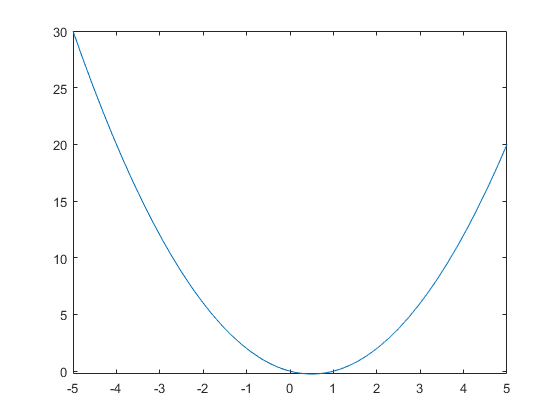

f = @(x) x.^2 - x;

%fplot() is a function function

fplot(f) %default range is from -5 to 5

# **matlabFunction()**

This command converts a ***symbolic**** function* to an ***anonymous ****function, *allowing it to be passed in a MATLAB function **function**, which is a function that accepts function handles as arguments.

syms x 
sym_function = x^2 + 2*x

$$sym\_function = x^{2}+2\,x$$

an_function = matlabFunction(sym_function)

an_function = function_handle with value:
    @(x)x.*2.0+x.^2
